# Inverted Pendulum

# Final Project

#### Project Team:

Nick Wakefield (TA: Brian Collery, Lab Section: L01 )

Kevin McManus (TA: Anthony Caine, Lab Section:L08)

## The Inverted Pendulum

The figure below shows the system under examination. The variables $x$  which is the horizontal position of the cart and $\theta$, the tilt angle angle of the pendulum  are outputs, that is, they are  determined by physics of  the system. The others are  parameters that specify the properties of the system.

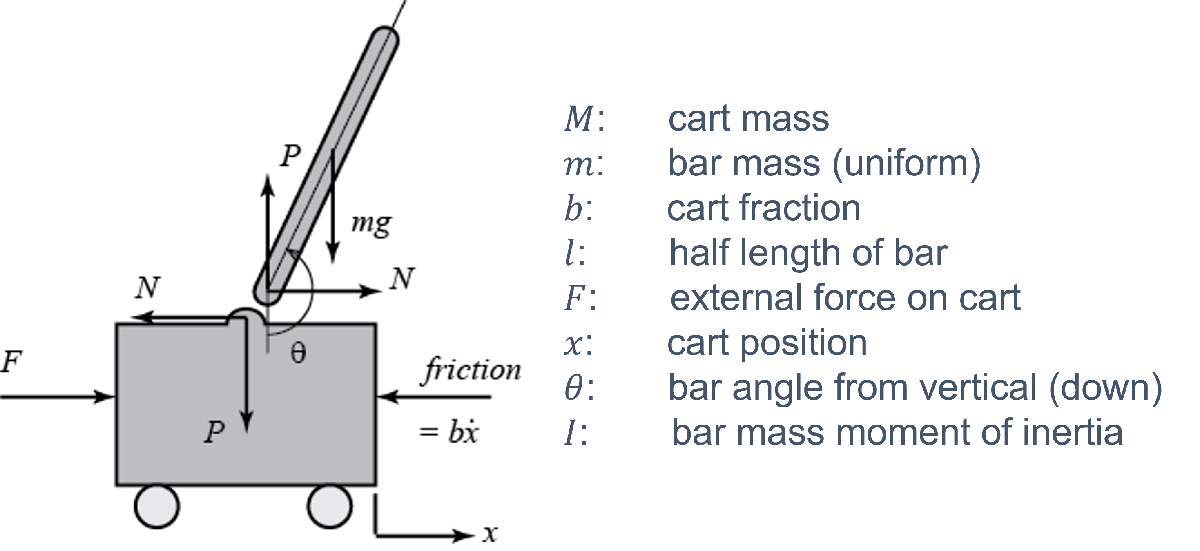

This system couples two second order differential equations with four unknowns:


$$\matrix{
(M+m)\ddot{x} + b\dot{x} +ml\cos{\ddot{\theta}} - ml\dot{\theta}^2\sin{\theta}& =& F\cr
(I+ml^2)\ddot{\theta} + mgl\sin{\theta} &=& -ml\ddot{x}\cos{\theta}
}$$


These equations define four state variables: $V(t) = \pmatrix{
x \cr x'\cr \theta \cr \theta'
}$ which we model as a function of time $t$.

In the sections that follow, we explore nonlinear and linear models of the behavior of this system. In both cases, we use Euler's method to approximate $V(t)$, that is:


$$\matrix{
dV_t &=& f(V_{t-1})\cr
V_t &=& V_{t-1} + dV_t dt
}$$


given some starting state $V_0$. The function $f$ above is either the non-linear system above or a linear simplification of it.

#### Nonlinear Approximation

The physics of this problem produces the following two equations:


$$\matrix{
(M+m)\ddot{x}+ml\cos{\theta}\ddot{\theta} &=&ml\dot{\theta}^2\sin{\theta} - b\dot{x} +F\cr
ml\cos{\theta}\ddot{x} +(I+ml^2)\ddot{\theta} &=& -mgl\sin{\theta}
}$$


which can be reduced to


$$\matrix{
A\ddot{x} + B\ddot{\theta} &=& S \cr
C\ddot{x} +D\ddot{\theta} &=& T
} $$


where:


$$\matrix{
A &=& M+m\cr
B &=&ml\cos{\theta} \cr
C &=&ml\cos{\theta} \cr
D & = &I+ml^2 \cr
S &=& ml\dot{\theta}^2 \sin{\theta} -b\dot{x} + F\cr
T &=& -mgl\sin{\theta}
}$$


Given these variables,


$$\matrix{
\ddot{x} &=& \frac{SD-BT}{AD-BC} \cr
\ddot{\theta} &=& \frac{AT-CS}{AD-BC}
}$$


Similar to the Euler Approximation, the nonlinear approximation computes $dV$ for each timestep and adds it to the state variable $V$ computed for the previous timestep. For timestep $t$ the calculation is:


$$V_t = V_{t-1} + dV_tdt$$


where: $dV_t = \pmatrix{
\dot{x_{t-1} \cr
\ddot{x_t} \cr
\dot{\theta_{t-1}\cr
\ddot{\theta_t} \cr
}$ and $\ddot{x}$ and $\ddot{\theta}$ are calculated from the constants above which are in turn calculated from the state variables from the previous timestep.

The project document specified no control system for the nonlinear system so the simulations in the next section do not contain any.

#### Simulations

With no force applied to the cart and the pendulum initially in the upright position, the system is in equilibrium: nothing moves. The figure below shows no change in the $x$ position of the cart and the $\phi$ angle of the pendulum over the 20 seconds of the simulation. This illustrates Newton's first law: a system in equilibrium remains in equilibrium until an external force acts on it. This is an unstable equilibrium as even the slightest force or off-vertical pendulum position will move the system to a different equilibrium.

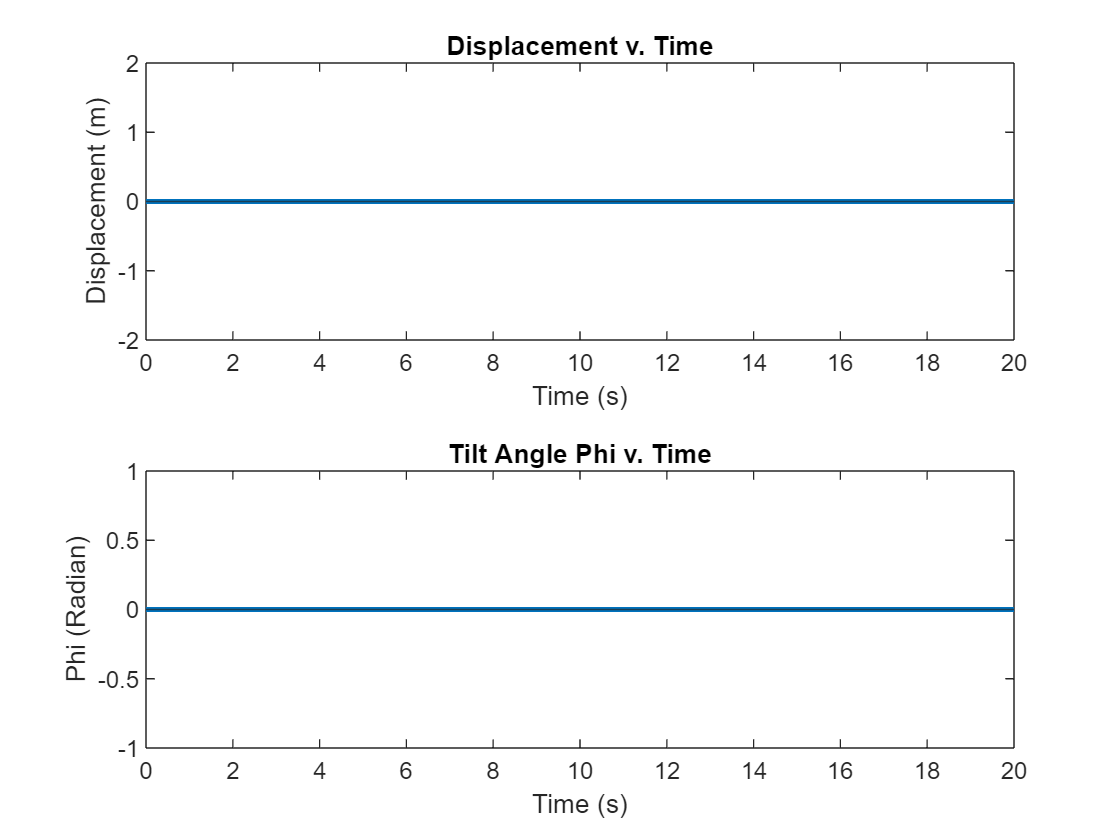

V0 = [0;0;0;0];
time_t = [0:0.001:20];

force = 0;
descr = sprintf('Forece: %.2f', force);

IP = InvertedPendulum();

sr = IP.nonlinear_method(V0,force, time=time_t, description=descr);

tiledlayout(2,1)
nexttile
sr.plotX
ylim([-2 2])
nexttile
sr.plotPhi

If the pendulum is initially tilted a little bit left or right, it is off-balance and gravity accelerates the pendulum downward. The pendulum then enters into a damped harmonic motion, swinging clockwise and counterclockwise as the bottom panel in the figure below shows.

In this case, the pendulum swings down in a clockwise direction, at the bottom of its arc, it pulls the cart to the negative $x$ dircetion. As the pendulum swings back, the cart oscillates in the positive direction. After about 15 seconds, the cart oscillates around the origin.

Although difficult to see, the amplitude of the  angular displacement $\phi$ is gradually decreasing. This is due to the friction that the cart encounters in its motion. The friction gradually bleeds energy from the system, which dampens the cart's motion which in turn dampens the pedulum's motion.

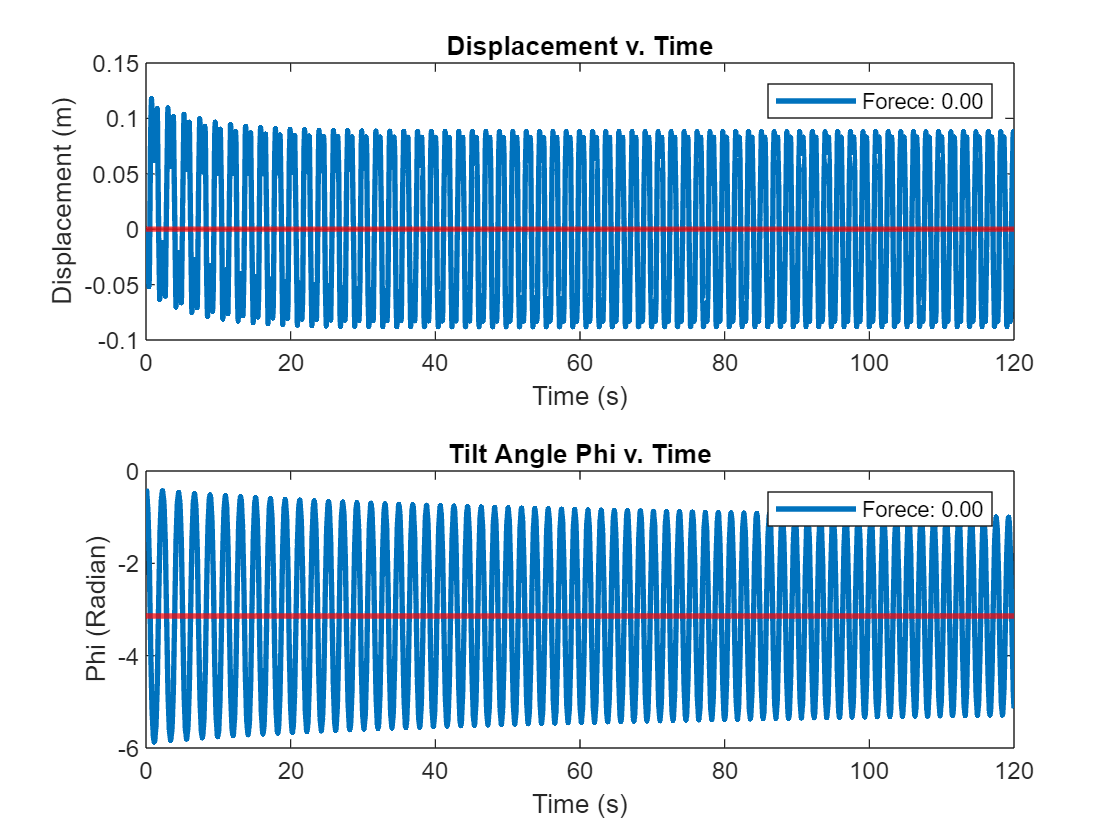

V0 = [0;0;-pi/8;0];
time_t = [0:0.001:120];
force = 0;
descr = sprintf('Forece: %.2f', force);
IP = InvertedPendulum();

sr = IP.nonlinear_method(V0,force, time=time_t, description=descr);

tiledlayout(2,1)
nexttile

sr.plotX
yline(0, LineWidth=2, color='red', HandleVisibility='off')
legend
nexttile
sr.plotPhi
yline(-pi, LineWidth=2, color='red', HandleVisibility='off')
legend

#### The Damping Effect of Friction

The nonlinear approximation reaches equilibrium in less time when the resistance (the factor $b$) is increased. The figure below shows such a result. After about 40 seconds, the pendulum settles down to its equilibrium position of $-\pi$, that is, straight down from the vertical position. In this simulation, since the force is set to zero, the inital position of the pendulum needed to be a bit  'off plumb' in order to get any motion in the system. In this simulation, we chose $\frac{\pi}{8}$ or 22.5 degrees tilted left as the pendulum's starting position.

The motion of the pendulum, which is no longer inverted, induces a force and therefore an acceleration and horizontal motion on the cart, which the bottom panel below illustrates. The cart oscillates horizontally with an initial amplitude of about 100 cm, eventually coming to rest at its starting point.

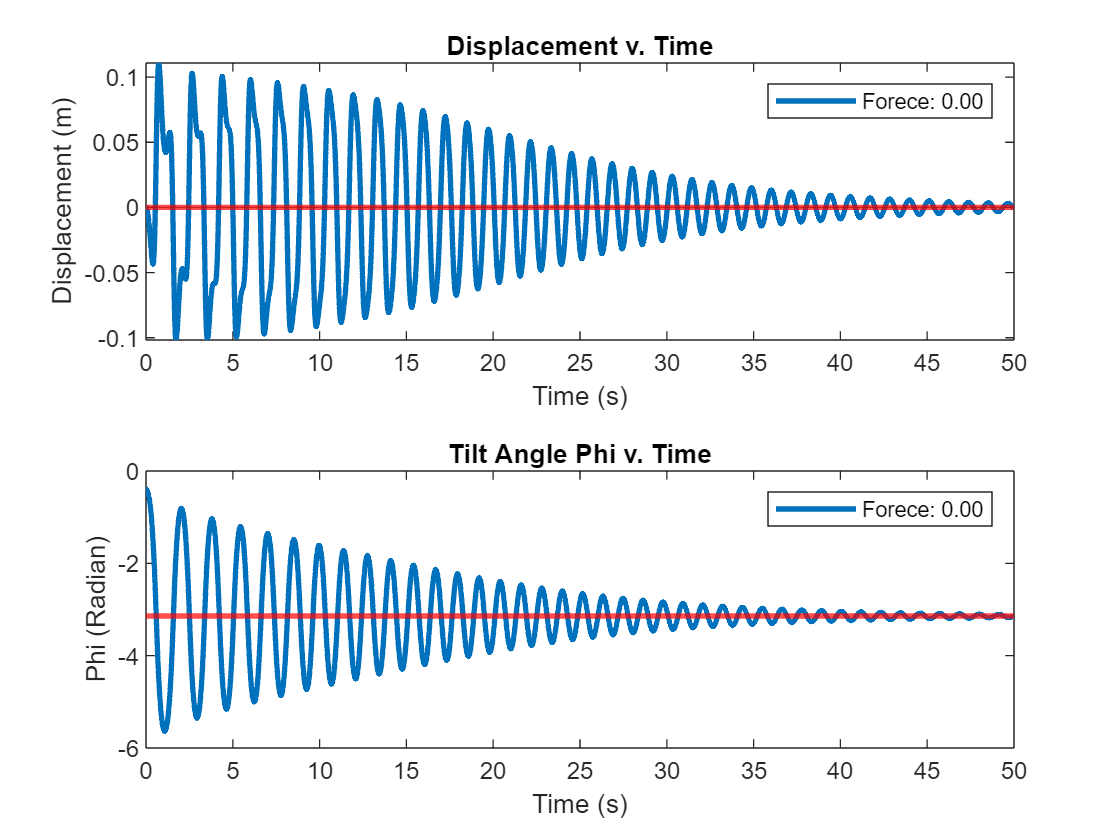

V0 = [0;0;-pi/8;0];
time_t = [0:0.005:50];
force = 0;
descr = sprintf('Forece: %.2f', force);

IP = InvertedPendulum("b",1.0);

sr1 = IP.nonlinear_method(V0, force, time=time_t, description=descr);

tiledlayout(2,1)
nexttile
sr1.plotX
yline(0, LineWidth=2, color='red', HandleVisibility='off')
legend
nexttile
sr1.plotPhi
yline(-pi, LineWidth=2, color='red', HandleVisibility='off')
legend;
hold off

This figure compares the two carts experiencing low and high friction. It is clear from the chart the high friction cart comes to equilibrium much more quickly than the low friction cart.

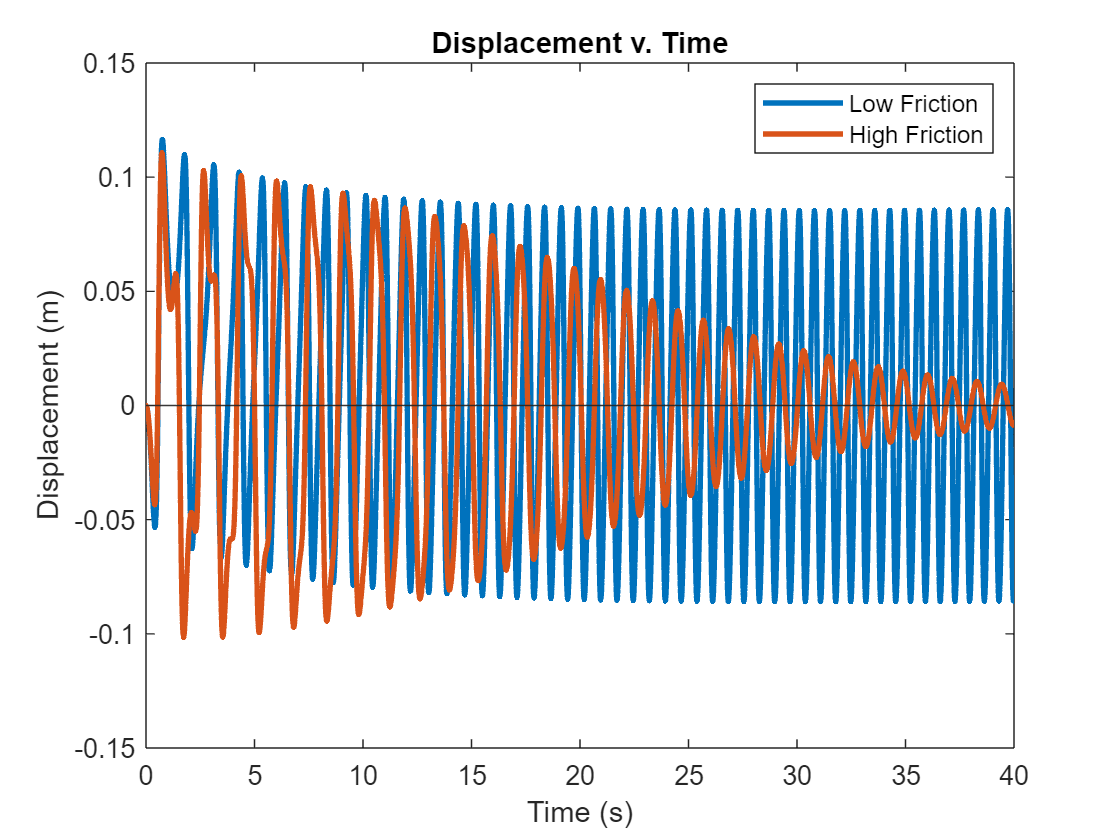

clf
V0 = [0;0;-pi/8;0];
time_t = [0:0.005:40];
force = 0;
IP = InvertedPendulum();

sr = IP.nonlinear_method(V0,force, time=time_t, description='Low Friction');
IP1 = InvertedPendulum("b",1.0);

sr1 = IP1.nonlinear_method(V0, force, time=time_t, description='High Friction');
sr.plotX
hold on
sr1.plotX
hold off

legend

#### Effect of Applied Force

A force applied to the cart will accelerate the system in the positive $x$ direction for the duration of the simulation. Eventually the motion of the pendulum settles to its' equilibrium postion ($-\pi$, i.e., down) and the cart keeps accelerating rightward. The figure below shows the results of applying  a 1 $N$ force to a cart with a resistance factor of $b=1 \frac{kg}{s}$ (10 $\times$ greater than the default). After 30 seconds the pendulum comes to rest but the cart keeps on moving.

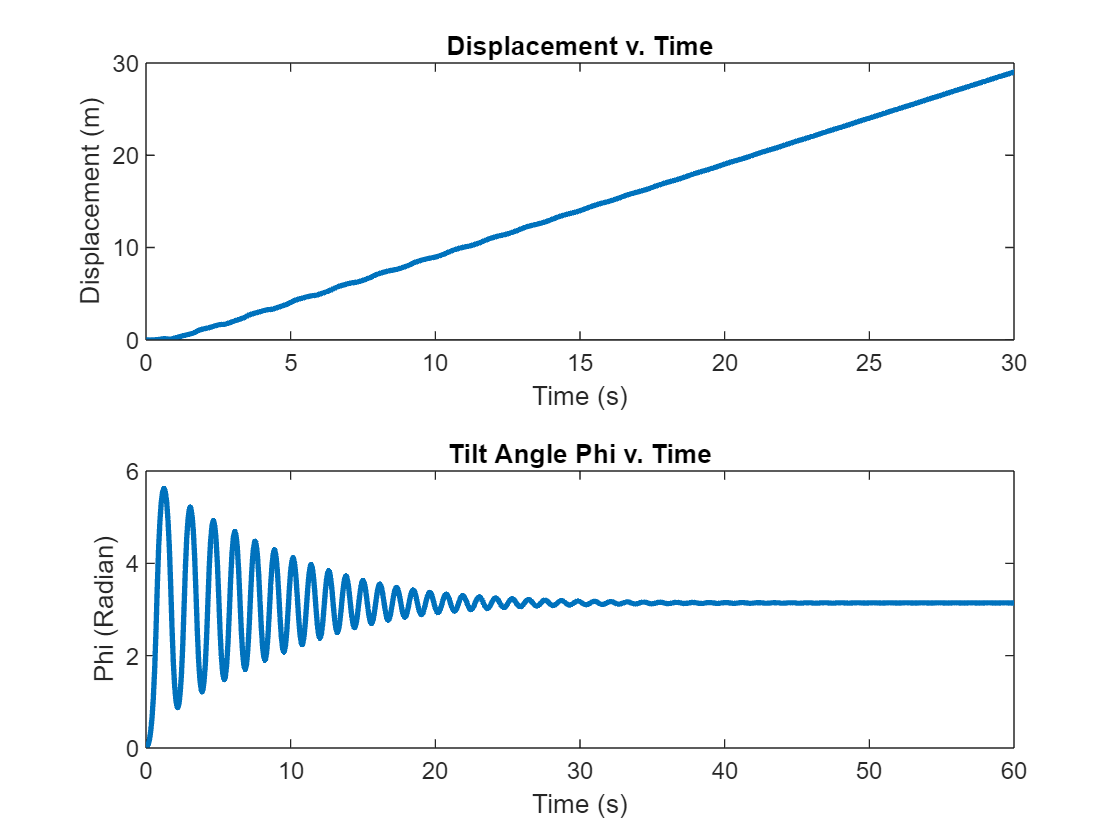

V0 = [0;-pi/8;0;0];
time_t = [0:0.001:60];

force = 1;
descr = sprintf('Forece: %.2f', force);

IP = InvertedPendulum(b=1.0);

sr = IP.nonlinear_method(V0,force, time=time_t, description=descr);
clf
tiledlayout(2,1)
nexttile
sr.plotX
xlim([0,30])
%ylim([-2 2])
nexttile
sr.plotPhi

## Linear Approximations (with Control)

Variable force: The effect of increasing the initial force component (F) is an exponential increase trend in displacement which is consistent with the physics of a moving pendulum with friction. With a large force applied to the system, pendulum will swing back and forth a greater number of times before eventually being halted by the bleeding of energy due to friction. This explanation can be seen in the figure below where the total displacement of the system is increasing with the amount of initial force applied.

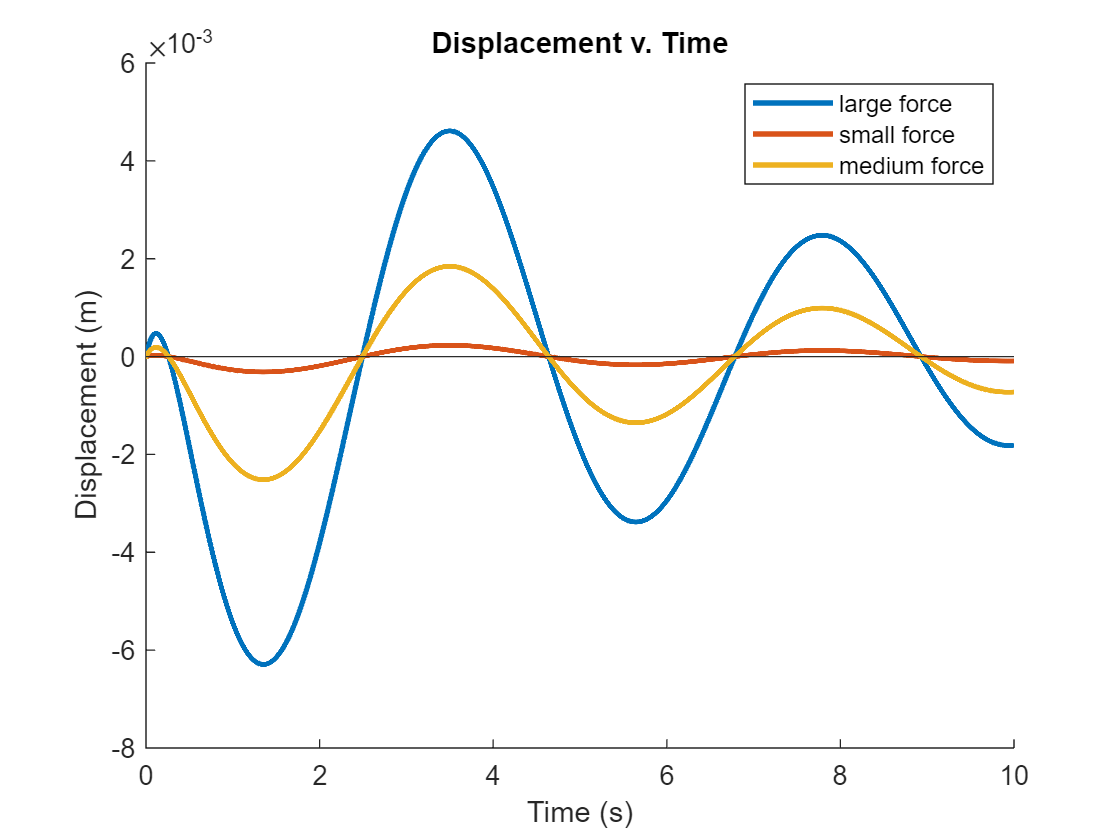

time_t = 0:0.001:10;
IP = InvertedPendulum();
%V0 = [0;0; -0.175;0]; % initial bar tilt 10 degrees
V0 = [0;0; 0;0];
Q = [1 0 0 0;
     0 0 0 0;
     0 0 1 0;
     0 0 0 0];
figure(Name='Initial Force Comparison')
hold on
sr = IP.euler_method(V0, 5, time=time_t, description='large force', lqr=true,N=[1;0;0;0], ...
    Q=Q);
sr.plotX
sr2 = IP.euler_method(V0, 0.25, time=time_t, description='small force', lqr=true,N=[1;0;0;0], ...
    Q=Q);
sr2.plotX
sr3 = IP.euler_method(V0, 2, time=time_t, description='medium force', lqr=true,N=[1;0;0;0], ...
    Q=Q);
sr3.plotX
hold off
legend

### Friction Variable

Friction is a force that dissipates energy from the system. The result is a net loss in displacement when constant friction is present. 

This principle is demonstrated in the figure below where the absolute displacement of the system is decreasing with increasing friction (b). Friction is also a stabilizing force because its vector is negative relative to the origin of motion and scales with the initial force. The linear approximation uses a constant friction force for each example.

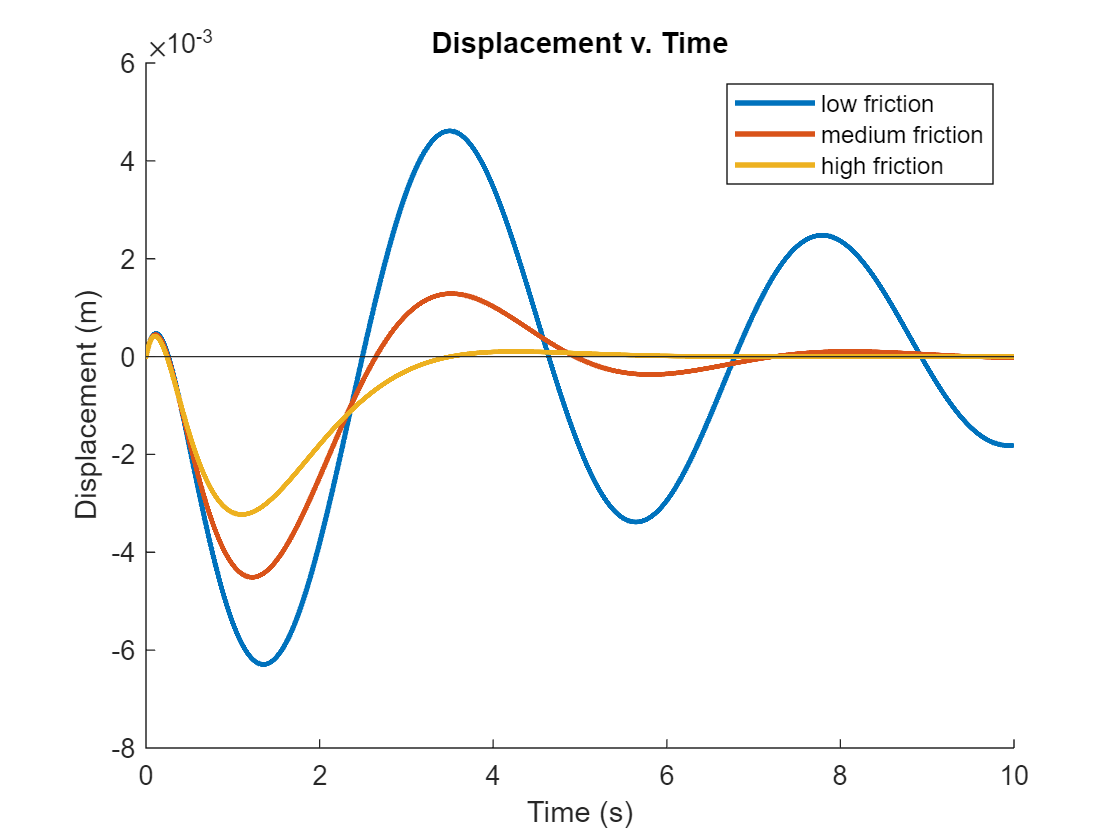

clf;
time_t = 0:0.001:10;
IP = InvertedPendulum();
IP2 = InvertedPendulum(b=0.5);
IP3 = InvertedPendulum(b=1);
%V0 = [0;0; -0.175;0]; % initial bar tilt 10 degrees
V0 = [0;0; 0;0];
Q = [1 0 0 0;
     0 0 0 0;
     0 0 1 0;
     0 0 0 0];
hold on
sr = IP.euler_method(V0, 5, time=time_t, description="low friction", lqr=true,N=[1;0;0;0], ...
    Q=Q);
sr.plotX
sr2 = IP2.euler_method(V0, 5, time=time_t, description="medium friction", lqr=true,N=[1;0;0;0], ...
    Q=Q);
sr2.plotX
sr3 = IP3.euler_method(V0, 5, time=time_t, description="high friction", lqr=true,N=[1;0;0;0], ...
    Q=Q);
sr3.plotX
hold off
legend

### Variable Cart Mass:

The moment of inertia is one of the most important variables to consider when analyzing a moving body because it dictates an object's relative resistance to motion. The absolute moment of inertia increases with the mass of an object according to the torque equation where $T=-L\left(\textrm{mgsin}\left(\theta \right)\right)$. The negative sign indicates that the torque acts on the opposite side of the angular displacement. The equation can be rewritten as $I\alpha =-L\left(\textrm{mgsin}\left(\theta \right)\right)$. Upon analysis of the cart below, the total displacement of the pendulum is decreasing with increasing cart mass which is consistenent with an increasing moment of inertia.

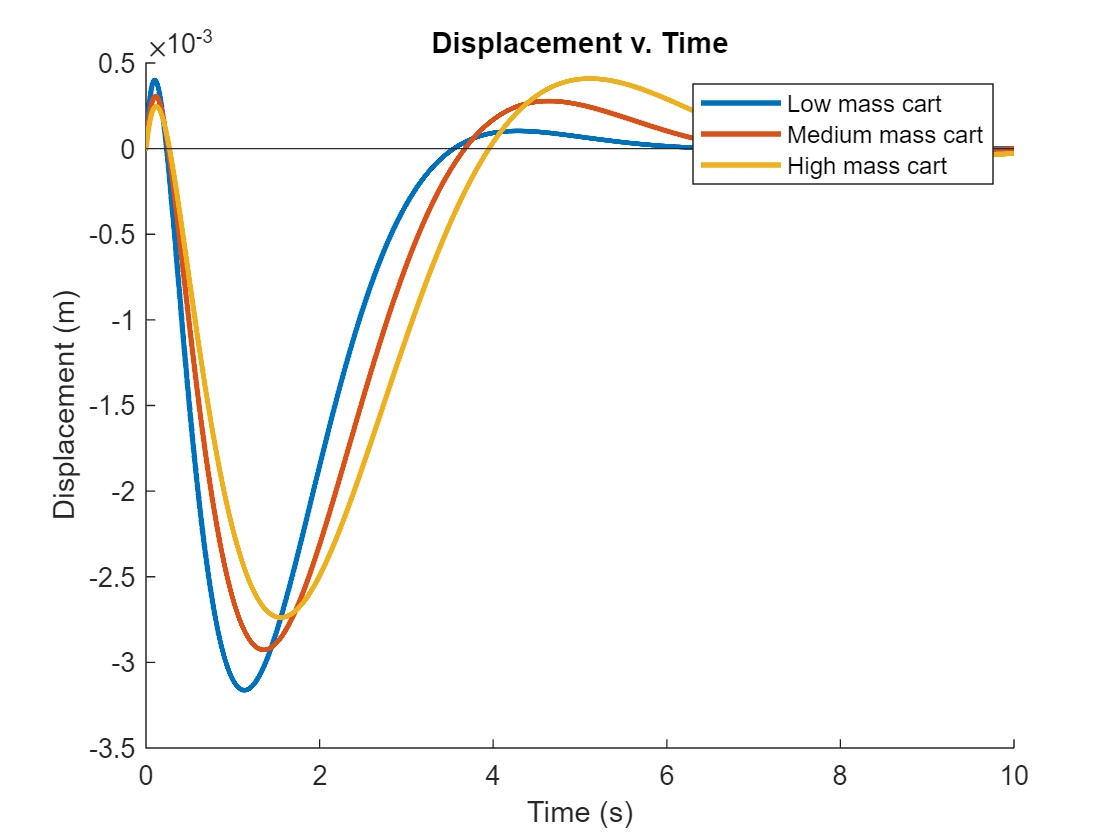

clf;
time_t = 0:0.001:10;
IP = InvertedPendulum();
IP2 = InvertedPendulum(M=0.75);
IP3 = InvertedPendulum(M=1);
%V0 = [0;0; -0.175;0]; % initial bar tilt 10 degrees
V0 = [0;0; 0;0];
hold on
sr = IP.euler_method(V0, 5, time=time_t, description="Low mass cart", lqr=true,N=[1;0;0;0], ...
    Q=eye(4));
sr.plotX
sr2 = IP2.euler_method(V0, 5, time=time_t, description="Medium mass cart", lqr=true,N=[1;0;0;0], ...
    Q=eye(4));
sr2.plotX
sr3 = IP3.euler_method(V0, 5, time=time_t, description="High mass cart", lqr=true,N=[1;0;0;0], ...
    Q=eye(4));
sr3.plotX
hold off
legend

### Initial Pendulum Position:

The initial position of the pendulum is important because of gravitation potential energy whereby the further the angle the pendulum starts from its equilibrium point the more potential energy is contained within the system initially. The trend in the figure below clearly indicates a greater amount of displacement is observed in the pendulum with increasing potential energy.

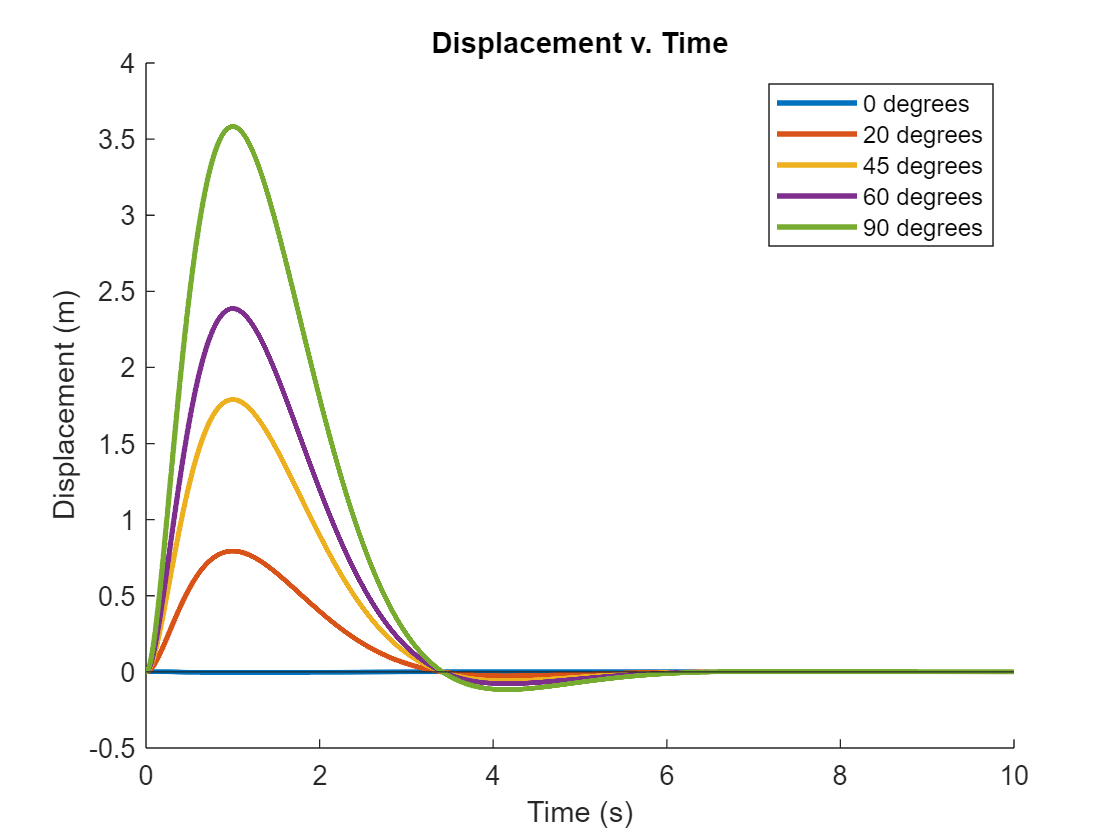

clf;
time_t = 0:0.001:10;
IP = InvertedPendulum();
%V0 = [0;0; -0.175;0]; % initial bar tilt 10 degrees
V01 = [0;0;0;0];
V02 = [0;0;-0.349;0];
V03 = [0;0;-0.785;0];
V04 = [0;0;-1.047;0];
V05 = [0;0;-1.571;0];
hold on
sr = IP.euler_method(V01, 5, time=time_t, description="0 degrees", lqr=true,N=[1;0;0;0], ...
    Q=eye(4));
sr.plotX
sr2 = IP.euler_method(V02, 5, time=time_t, description="20 degrees", lqr=true,N=[1;0;0;0], ...
    Q=eye(4));
sr2.plotX
sr3 = IP.euler_method(V03, 5, time=time_t, description="45 degrees", lqr=true,N=[1;0;0;0], ...
    Q=eye(4));
sr3.plotX
sr4 = IP.euler_method(V04, 5, time=time_t, description="60 degrees", lqr=true,N=[1;0;0;0], ...
    Q=eye(4));
sr4.plotX
sr5 = IP.euler_method(V05, 5, time=time_t, description="90 degrees", lqr=true,N=[1;0;0;0], ...
    Q=eye(4));
sr5.plotX
hold off
legend

### Scaler multiples of LQR matrix

The control matrix provides a stabilizing effect on the pendulum like friction. As the control matrix was scaled with non zero components and constant initial values, the total displacement was reduced indicating the control matrix acts similar to a dampening force like friction in the figure above. This same trend is visible in the proceeding figure where all diagonal components of the LQR are set to constant values and scaled. Using an LQR with all diagonal components included, the total displacement appears to dampened by the same magnitude, but instead a higher percentage of the total pendulum displacement is in the negative direction.

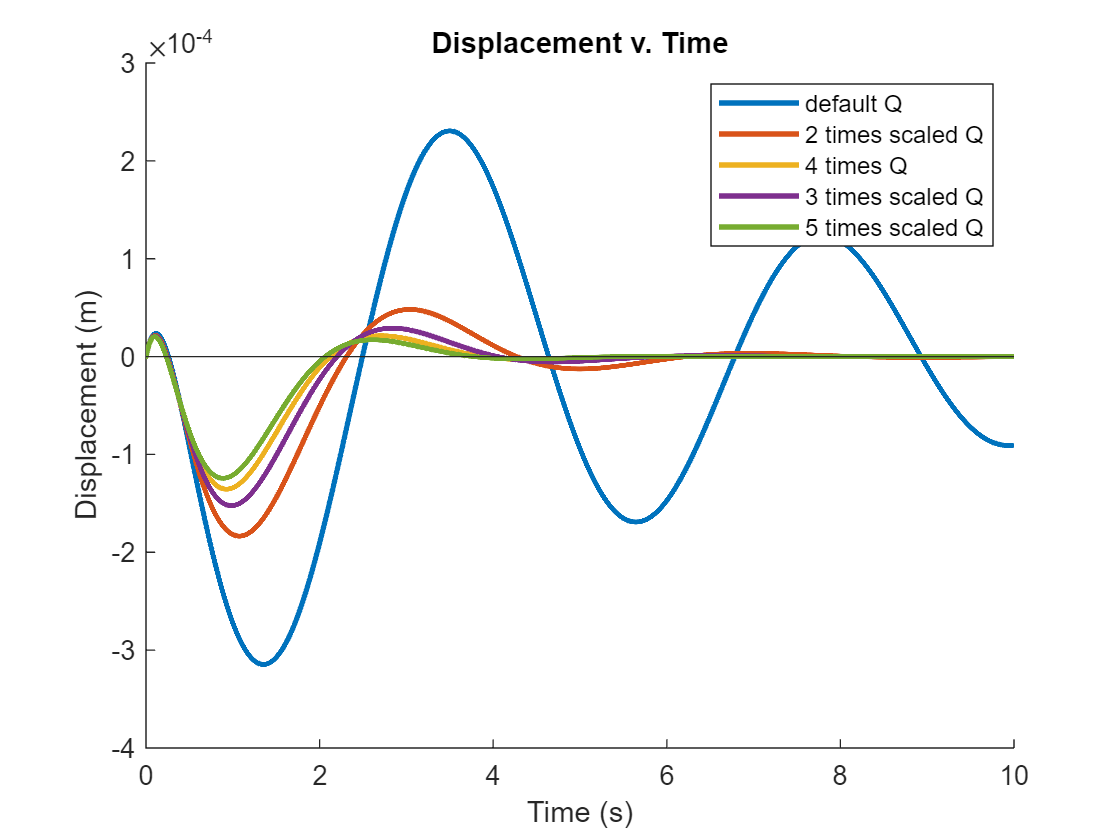

clf;
time_t = 0:0.001:10;
V0 = [0;0;0;0];
Q=  [1 0 0 0;
    0 0 0 0;
    0 0 1 0;
    0 0 0 0];

Q1= [2 0 0 0;
    0 0 0 0;
    0 0 2 0;
    0 0 0 0];

Q2= [4 0 0 0;
    0 0 0 0;
    0 0 4 0;
    0 0 0 0];

Q3= [3 0 0 0;
    0 0 0 0;
    0 0 3 0;
    0 0 0 0];

Q4= [5 0 0 0;
    0 0 0 0;
    0 0 5 0;
    0 0 0 0];
IP = InvertedPendulum();
hold on
sr = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q, description='default Q');
sr.plotX;
sr2 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
     Q=Q1, description='2 times scaled Q');
sr2.plotX
sr3 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q2, description='4 times Q');
sr3.plotX
sr4 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q3, description='3 times scaled Q');
sr4.plotX
sr5 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q4, description='5 times scaled Q');
sr5.plotX
hold off
legend()

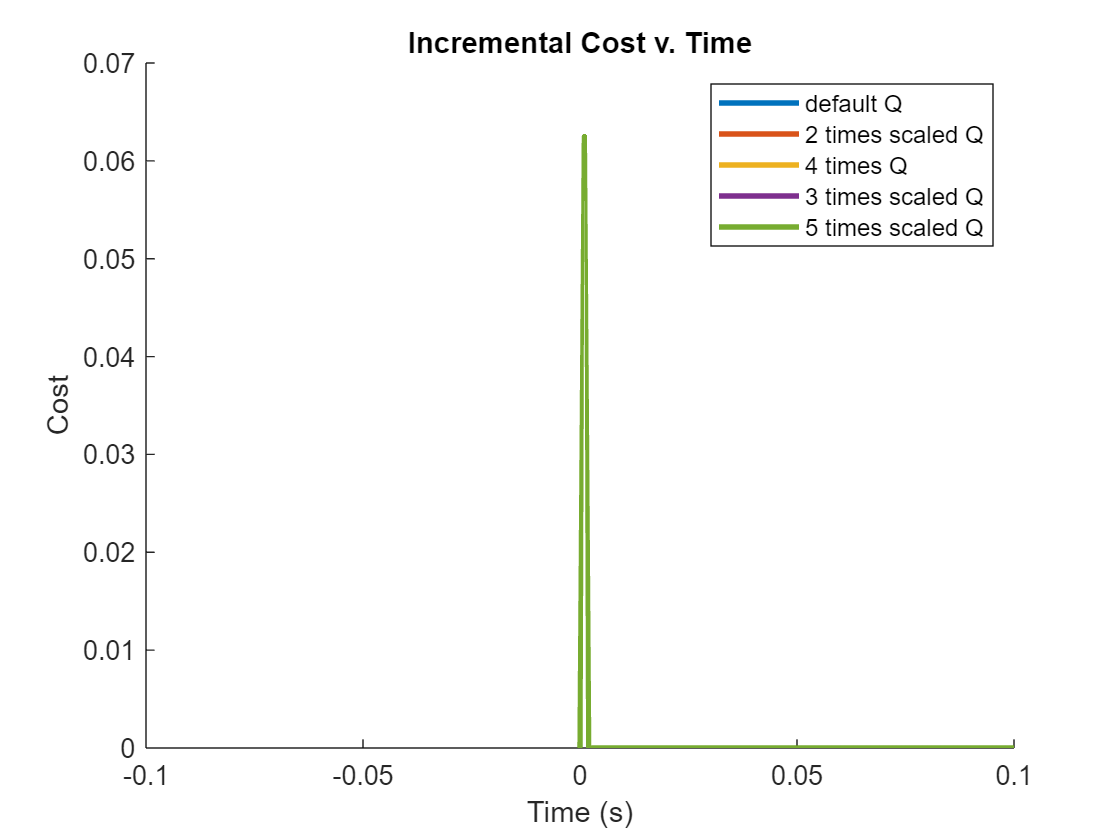

clf;
hold on
sr.plotdC;
sr2.plotdC;
sr3.plotdC;
sr4.plotdC;
sr5.plotdC;
hold off
xlim([-0.1 0.1]);
legend()

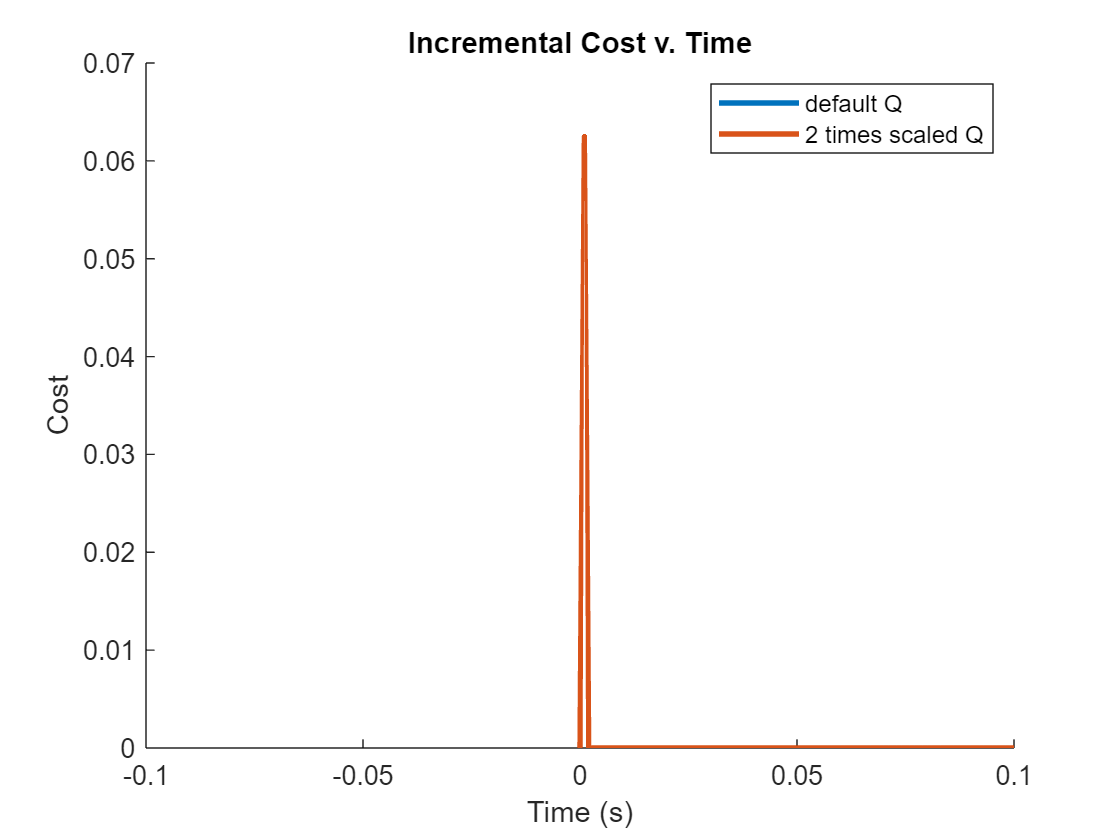



clf;
hold on
sr.plotdC(cumulative=false);
sr2.plotdC(cumulative=false);
%sr3.plotdC(cumulative=true);
%sr4.plotdC(cumulative=true);
%sr5.plotdC(cumulative=true);
hold off
legend()
xlim([-0.1 0.1])

Q matrix with all variables included and scaled See above explanation: 

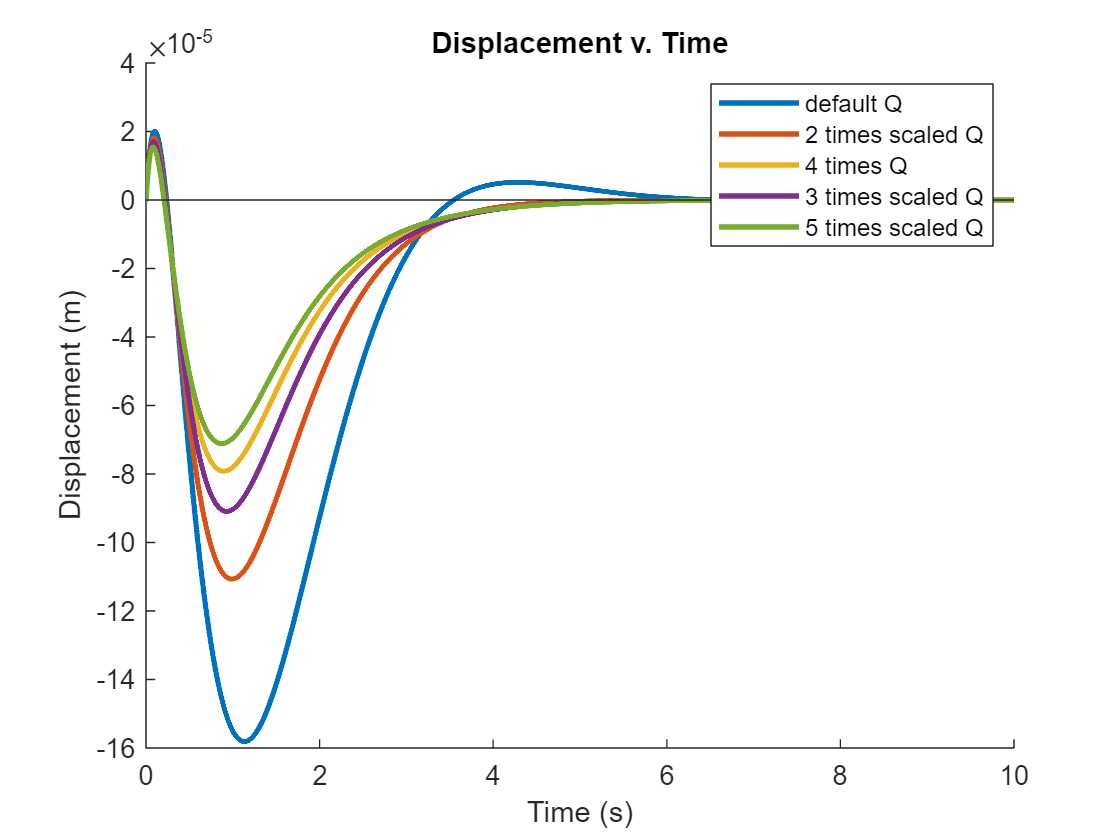

clf;
time_t = 0:0.001:10;
Q=  [1 0 0 0;
    0 1 0 0;
    0 0 1 0;
    0 0 0 1];

Q1= [2 0 0 0;
    0 2 0 0;
    0 0 2 0;
    0 0 0 2];

Q2= [4 0 0 0;
    0 4 0 0;
    0 0 4 0;
    0 0 0 4];

Q3= [3 0 0 0;
    0 3 0 0;
    0 0 3 0;
    0 0 0 3];

Q4= [5 0 0 0;
    0 5 0 0;
    0 0 5 0;
    0 0 0 5];
IP = InvertedPendulum();
hold on
sr = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q, description='default Q');
sr.plotX;
sr2 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
     Q=Q1, description='2 times scaled Q');
sr2.plotX
sr3 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q2, description='4 times Q');
sr3.plotX
sr4 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q3, description='3 times scaled Q');
sr4.plotX
sr5 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q4, description='5 times scaled Q');
sr5.plotX
hold off
legend()

Q matrix wtih different ratios of displacement (x) to phi and x' to phi': By observing the displacement graph it is clear that the displacement vector is not affected greatly by the angle of phi even when the value of phi is very large compared to displacement in ratio. This is does make sense since phi is only an angle of the starting point of the bar and there for will eventually go to equilbrium depending on the force applied. When the displacement value in the LQR matrix was scaled up, the overall displacement was reduced. The opposite effect can be seen when scaling up the angle phi, but the magnitude of difference in displacement of caused by phi appears fairly negligible. It's possible that this scaling issue arises from the fact that the units of phi are in radians and units of displacement are in meters.

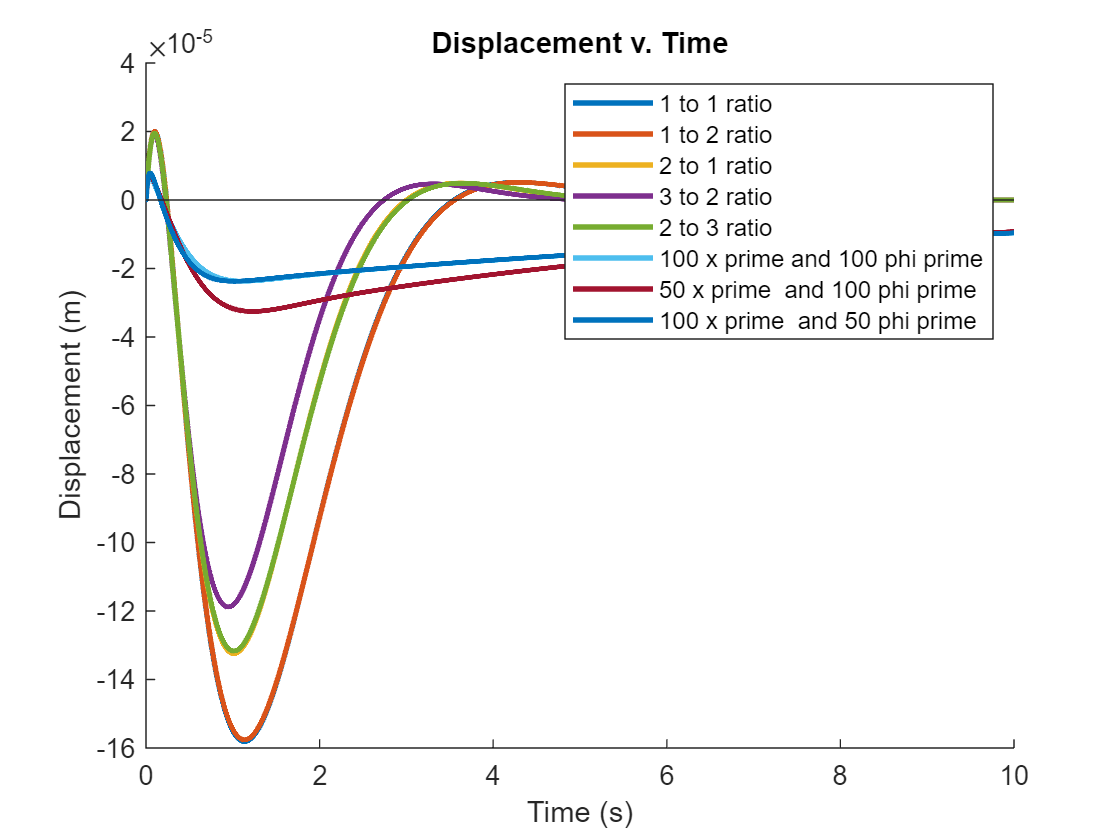

clf;
time_t = 0:0.001:10;
Q=  [1 0 0 0;
    0 1 0 0;
    0 0 1 0;
    0 0 0 1];

Q1= [1 0 0 0;
    0 1 0 0;
    0 0 2 0;
    0 0 0 1];

Q2= [2 0 0 0;
    0 1 0 0;
    0 0 1 0;
    0 0 0 1];

Q3= [3 0 0 0;
    0 1 0 0;
    0 0 2 0;
    0 0 0 1];

Q4= [2 0 0 0;
    0 1 0 0;
    0 0 3 0;
    0 0 0 1];

Q5= [1 0 0 0;
    0 100 0 0;
    0 0 1 0;
    0 0 0 100];

Q6= [1 0 0 0;
    0 50 0 0;
    0 0 1 0;
    0 0 0 100];

Q7= [1 0 0 0;
    0 100 0 0;
    0 0 1 0;
    0 0 0 50];
IP = InvertedPendulum();
hold on
sr = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q, description='1 to 1 ratio');
sr.plotX;
sr2 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
     Q=Q1, description='1 to 2 ratio');
sr2.plotX
sr3 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q2, description='2 to 1 ratio');
sr3.plotX
sr4 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q3, description='3 to 2 ratio');
sr4.plotX
sr5 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q4, description='2 to 3 ratio');
sr5.plotX
sr6 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q5, description='100 x prime and 100 phi prime');
sr6.plotX
sr7 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q6, description='50 x prime  and 100 phi prime');
sr7.plotX
sr8 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q7, description='100 x prime  and 50 phi prime');
sr8.plotX
hold off
legend()

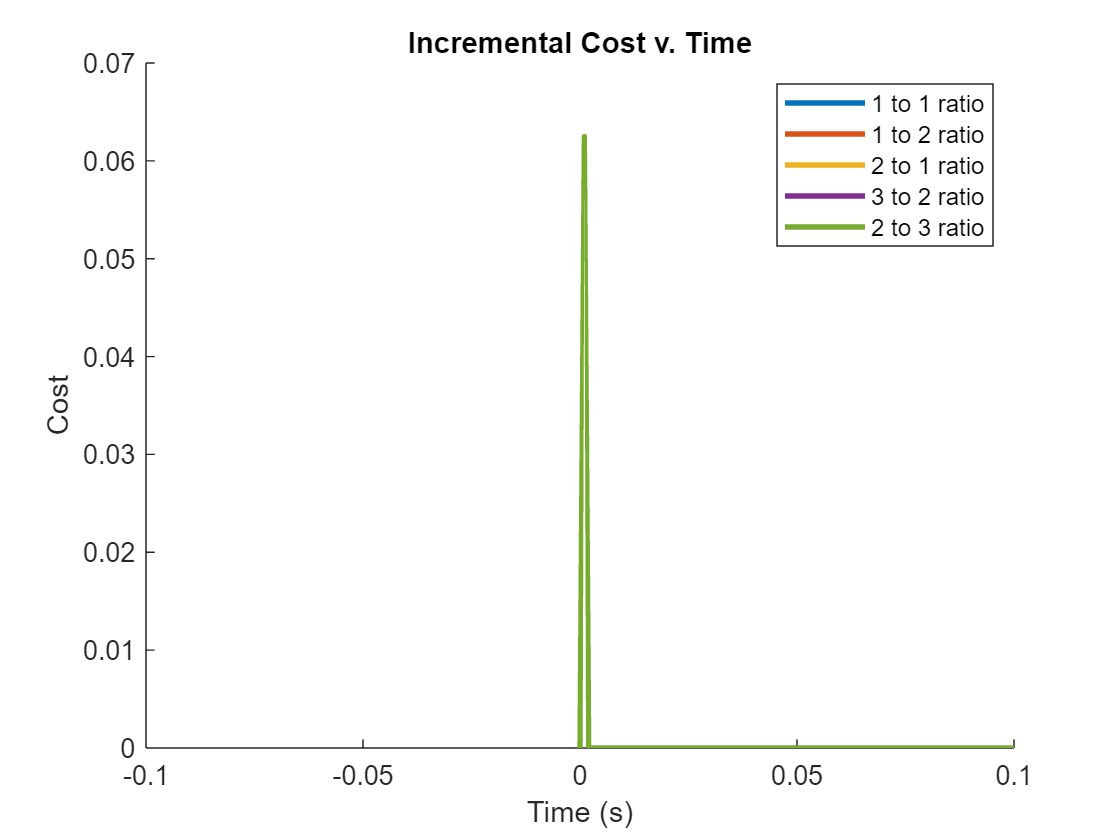

clf;
hold on
sr.plotdC;
sr2.plotdC;
sr3.plotdC;
sr4.plotdC;
sr5.plotdC;
hold off
xlim([-0.1 0.1]);
legend()

### With and Without LQR matrix

The system is unstable without the LQR matrix present. The result of the LQR matrix being absent is that the pendulum’s displacement will increase to infinity in the negative directrion. If you do not have the LQR, you violate the assumptions of the model which dictate that the angle of phi is small. 

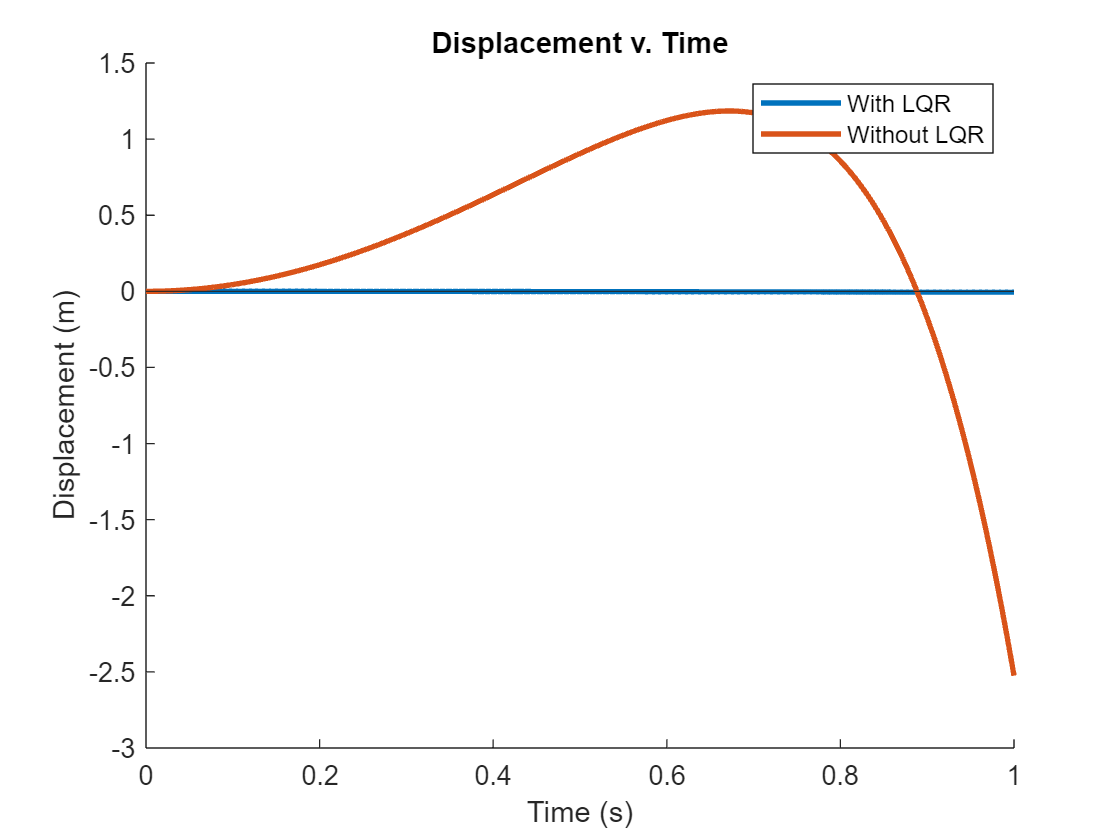

clf;
time_t = 0:0.001:10;
IP = InvertedPendulum();
%V0 = [0;0; -0.175;0]; % initial bar tilt 10 degrees
V0 = [0;0; 0;0];
Force = 5;
Q = [1 0 0 0;
     0 0 0 0;
     0 0 1 0;
     0 0 0 0];
figure(Name='Initial Force Comparison')
hold on
sr = IP.euler_method(V0, 5, time=time_t, description='With LQR', lqr=true,N=[1;0;0;0], ...
    Q=Q);
sr.plotX
sr2 = IP.euler_method(V0, 5, time=time_t, description='Without LQR', lqr=false,N=[1;0;0;0], ...
    Q=Q);
sr2.plotX
hold off 
legend()
xlim([0,1])

## Linear Quadratic Regulation (LQR)

## LQR: Cost and Effective Force

Linear Quadratic Regulation acheives its regulation by modifying the force that is applied to the system. After each time step, the force is adjusted through the internal parameter $u$. The amount of adjustment is determined by an internal $K$ matrix, computed at the start of the simulation. $K$ is computed such that it minimizes a cost function. Cost is essentially a measure of energy expenditure.

The figure below shows the incremental cost or energy expenditure computed at each iteration step. It drops by two orders of magnitude after the first few iterations, and then converges to zero. 

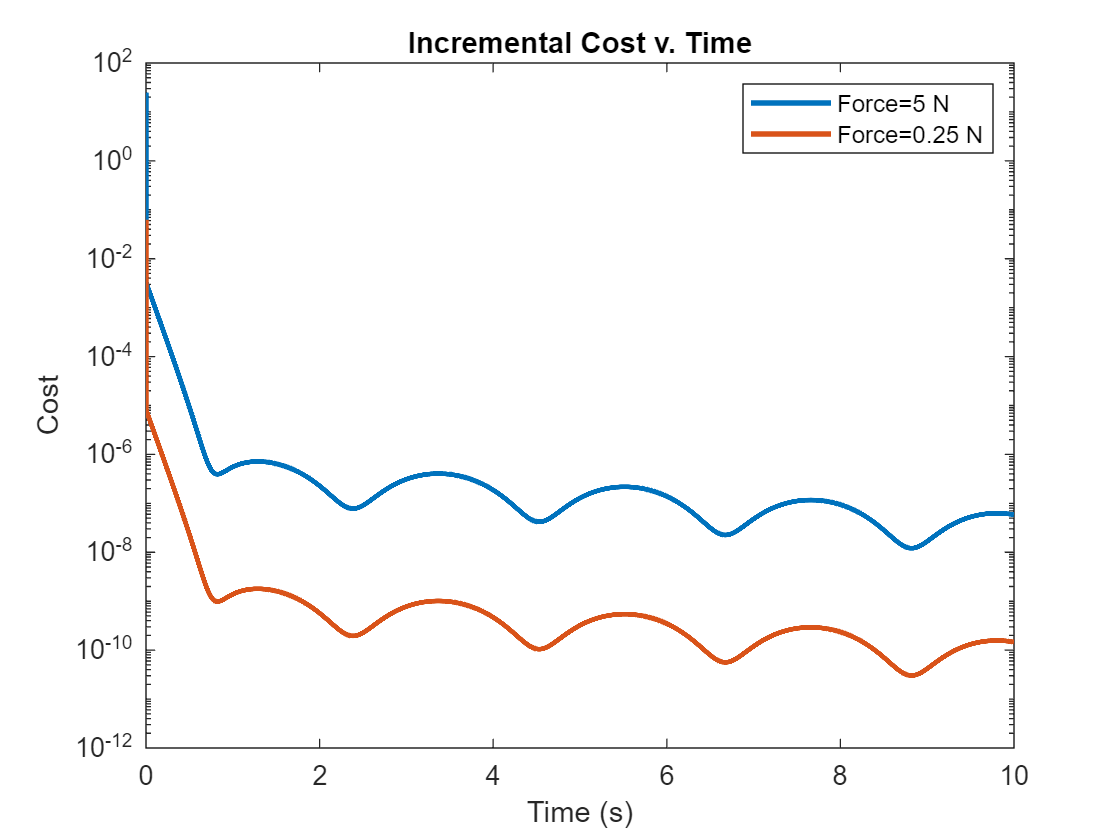

time_t = [0:0.001:10];

IP = InvertedPendulum();

V0 = [0;0; 0;0]; % Initial position

%non-default LQR 'Q' matrix that includes only X and phi:
Q = [1 0 0 0;
     0 0 0 0;
     0 0 1 0;
     0 0 0 0];

% create the inverted pendulum
IP = InvertedPendulum();

%simulate and plot the 5 Newton force
sr = IP.euler_method(V0, 5, time=time_t, lqr=true, ...
    Q=Q, description='Force=5 N');
sr.plotdC(cumulative=false);

%simulate and plot the 0.25 Newton force
sr2 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
     Q=Q, description='Force=0.25 N');
hold on
sr2.plotdC(cumulative=false)
hold off

legend()

The cumulative cost, that is the total energy expenditure over the time frame of the solution, rises steeply at first, then levels out. In the scale of the graphs below, each major tick is $10^{-3}$ seconds which is the timestep of the simulation. The graphs show, therefore, that most of the LQR impact is within the first few  time steps.

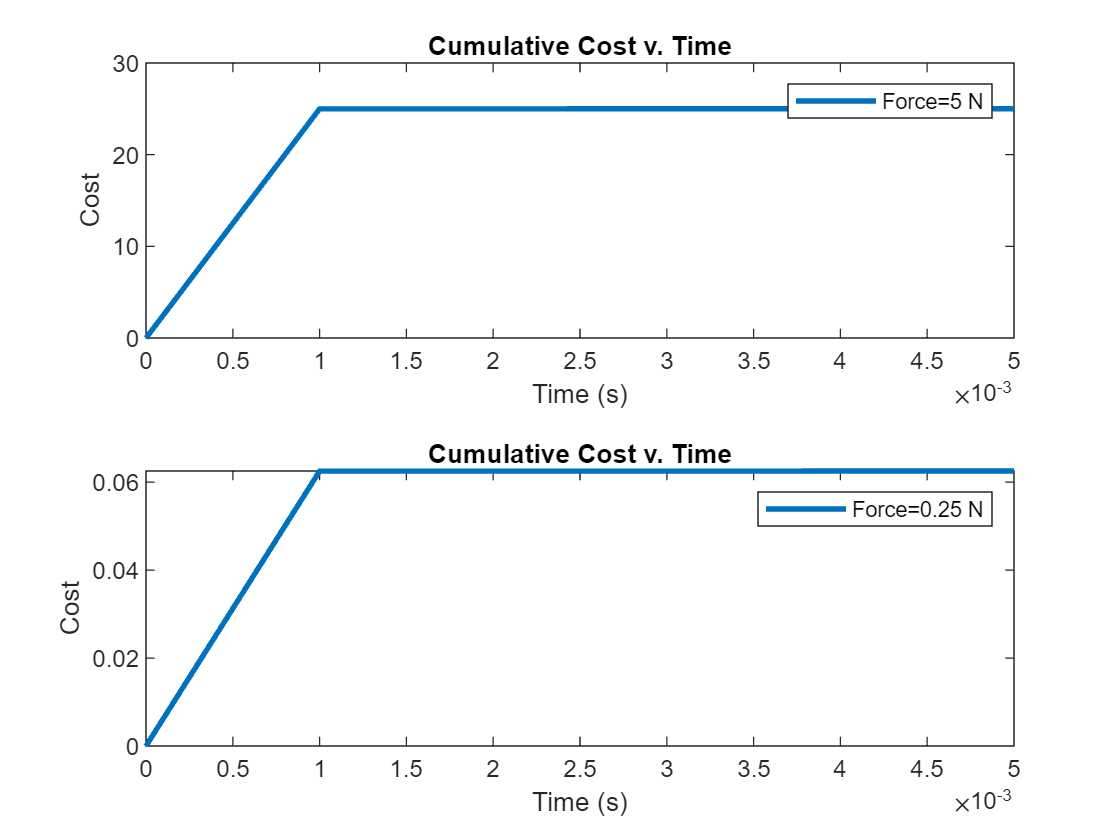

clf
tiledlayout(2,1)
nexttile
sr.plotdC(cumulative=true)
xlim([0 0.005])
legend
nexttile
sr2.plotdC(cumulative=true)
xlim([0 0.005])
legend

LQR works by adjusting the force applied to the system after each iteration. The internal parameter $u$ is the effective force. The figure below shows $u$ for the two simulations over the first few timesteps. LQR quickly reduces $u$ to near-zero which means that the lateral force applied to the cart lasts for only a few milliseconds. The removal of force, then allows the cart to bleed off energy and return to equilibrium.

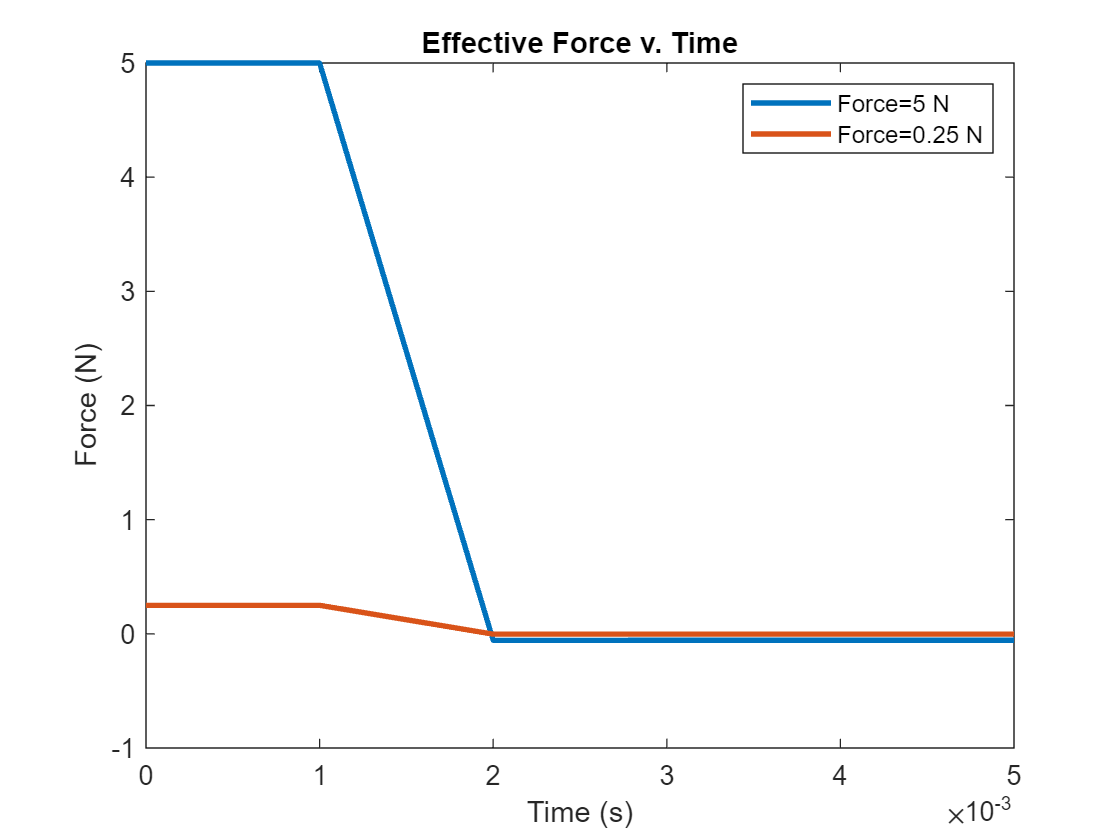

clf
sr.plotu()
hold on
sr2.plotu()
hold off
xlim([0  0.005])
legend